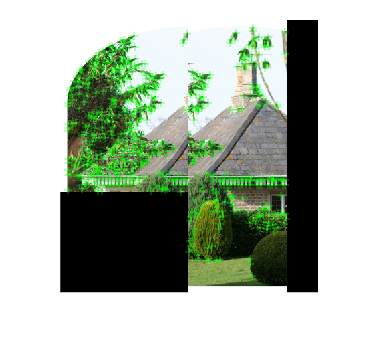

left = imread("leftleft.png");
right = imread("leftright.png");
corners_left = detectHarrisFeatures(im2gray(left));
corners_right = detectHarrisFeatures(im2gray(right));
figure;
combined = zeros(size(left));
combined = [combined combined];
combined(1:size(left,1),1:size(left,2),1:size(left,3)) = left;
combined(1:size(right,1),size(left,2):size(left,2)+size(right,2)-1,1:size(right,3)) = right;
combined = uint8(combined);
imshow(combined);
hold on;
quantity = 500;
strongest_left = corners_left.selectStrongest(quantity);
strongest_right = corners_right.selectStrongest(quantity);
strongest_left.Location = fliplr(strongest_left.Location);
strongest_right.Location = fliplr(strongest_right.Location);
plot(strongest_left.Location(:,2),strongest_left.Location(:,1),"g+");
plot(strongest_right.Location(:,2)+size(left,2),strongest_right.Location(:,1),"g+");

quantity = min(quantity,min(length(strongest_right),length(strongest_left)))

quantity = 274

radius = 8;
sobel = [-1 -2 -1; 0 0 0; 1 2 1];
offset_left_horiz = zeros(size(left,1:2)+[2*radius,2*radius]);
offset_left_vert = zeros(size(left,1:2)+[2*radius,2*radius]);
offset_left_horiz(radius+1:end-radius,radius+1:end-radius) = conv2(im2gray(imgaussfilt(left,3)),sobel',"same");
offset_left_vert(radius+1:end-radius,radius+1:end-radius) = conv2(im2gray(imgaussfilt(left,3)),sobel,"same");
offset_right_horiz = zeros(size(right, 1:2)+[2*radius,2*radius]);
offset_right_vert = zeros(size(right, 1:2)+[2*radius,2*radius]);
offset_right_horiz(radius+1:end-radius,radius+1:end-radius) = conv2(im2gray(imgaussfilt(right,3)),sobel',"same");
offset_right_vert(radius+1:end-radius,radius+1:end-radius) = conv2(im2gray(imgaussfilt(right,3)),sobel,"same");

minxy = double(uint32(strongest_right.Location));
maxxy = double(uint32(strongest_right.Location+2*radius));
descriptors_right = zeros(128,1,length(minxy));
for i=1:size(descriptors_right,3)
    descriptors_right(:,:,i) = sift_descriptor(offset_right_horiz, offset_right_vert, minxy, maxxy, i, radius);
end

selected_points = zeros(quantity,2);
selected_points(:,1) = randperm(quantity,size(selected_points,1))';
matched_points = zeros(size(selected_points));
matched_points(:,2) = 10^12;
remaining_selected = true(size(selected_points,1),1);
remaining_matched = true(size(matched_points,1),1);

for j=1:20
    for i=1:length(selected_points)
        if ~remaining_selected(i)
            continue
        end
        minxy = double(uint32(strongest_left.Location(selected_points(i,1),:)));
        maxxy = double(uint32(strongest_left.Location(selected_points(i,1),:)+2*radius));
        descriptor_left = sift_descriptor(offset_left_horiz, offset_left_vert, minxy, maxxy, 1, radius);
        sd = (descriptors_right(:,:,remaining_matched)-descriptor_left).^2;
        ssd = sum(sd,1:2);
        ssd = squeeze(ssd);
        [v,idx] = min(ssd);
        idx = find(remaining_matched==1,idx,"first");
        idx = idx(end);
        if v<matched_points(idx,2)
            if matched_points(idx,1)>0
                selected_points(matched_points(idx,1),2) = 0;
            end
            selected_points(i,2) = idx;
            matched_points(idx,1) = i;
            matched_points(idx,2) = v;
        end
    end
    remaining_selected = selected_points(:,2)==0;
    remaining_matched = matched_points(:,1)==0;
    sum(remaining_selected)
    if sum(remaining_selected)==0
        break
    end
end

ans = 155

ans = 84

ans = 49

ans = 33

ans = 24

ans = 15

ans = 10

ans = 5

ans = 2

ans = 1

ans = 0

old_selected_points = selected_points;
selected_points = selected_points(selected_points(:,2)~=0,:);

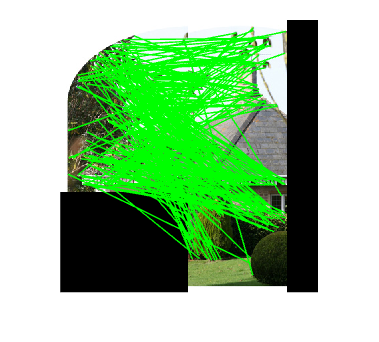

x1 = strongest_left.Location(selected_points(:,1),2);
y1 = strongest_left.Location(selected_points(:,1),1);
x2 = strongest_right.Location(selected_points(:,2),2)+size(left,2);
y2 = strongest_right.Location(selected_points(:,2),1);
figure;
imshow(combined);
hold on;
plot([x1,x2]',[y1,y2]',"g-");

slope_dev = 0.25;
length_dev = 0.25;
slopes = (y2-y1)./(x2-x1);
lengths = sqrt((y2-y1).^2.+(x2-x1).^2);
figure;
histogram(slopes)
m=mode(round(slopes,1));
s=slope_dev*std(slopes)

s = single
0.1787

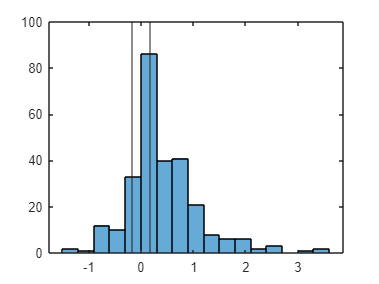

xline(m+s)
xline(m-s)

slope_inliers = (m-s)<slopes & slopes<(m+s);
figure;
histogram(lengths)
m=mode(round(lengths,-1))

m = single
70

s=length_dev*std(lengths)

s = single
19.1834

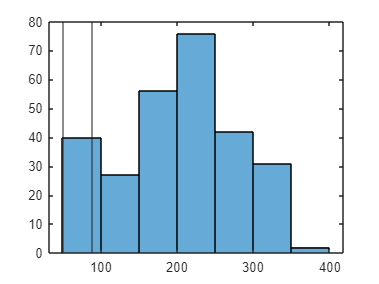

xline(m+s)
xline(m-s)

length_inliers = (m-s)<lengths & lengths<(m+s);
inliers = slope_inliers & length_inliers;
sum(inliers)

ans = 35

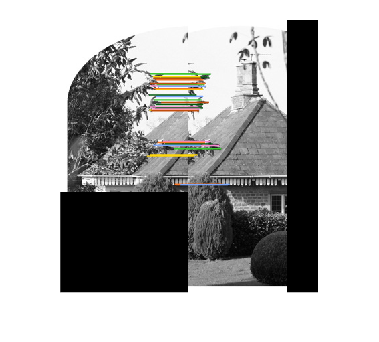

x1_filtered = strongest_left.Location(selected_points(inliers,1),2);
y1_filtered = strongest_left.Location(selected_points(inliers,1),1);
x2_filtered = strongest_right.Location(selected_points(inliers,2),2)+size(left,2);
y2_filtered = strongest_right.Location(selected_points(inliers,2),1);
figure;
imshow(im2gray(combined));
hold on;
plot([x1_filtered,x2_filtered]',[y1_filtered,y2_filtered]',"-");
colororder("meadow");

function descriptor = sift_descriptor(horiz, vert, minxy, maxxy, idx, rad)
    idcisx = linspace(minxy(idx,1),maxxy(idx,1),5);
    idcisy = linspace(minxy(idx,2),maxxy(idx,2),5);
    angxy = [1 1 0 -1 -1 -1  0  1;
           0 1 1  1  0 -1 -1 -1];
    edgexy = zeros([2*rad+1,2*rad+1,2]);
    edgexy(:,:,1) = horiz(idcisx(1):idcisx(end),idcisy(1):idcisy(end));
    edgexy(:,:,2) = vert(idcisx(1):idcisx(end),idcisy(1):idcisy(end));
    gradxy = reshape(reshape(edgexy,[],2)*angxy,2*rad+1,2*rad+1,[]);
    temp_des = zeros(4,4,8);
    idcisx = idcisx+1-idcisx(1);
    idcisy = idcisy+1-idcisy(1);
    for i=1:4
        for j=1:4
            temp_des(i,j,:) = sum(gradxy(idcisx(i):idcisx(i+1),idcisy(j):idcisy(j+1),:),1:2);
        end
    end
    descriptor = reshape(temp_des,[],1);
end